# Hodgkin-Huxley simulation

Some code to simulate an axon's response to an applied stimulus current based on the Hodgkin-Huxley equations as described in the 1952 paper (cited below). Allows for visualization of how the gating variables m, h, and n influence ionic currents and membrane voltage, how the gating variables change based on their respective rate constants a and B, and how those rate constants are dependent on the membrane voltage.

HODGKIN AL, HUXLEY AF. A quantitative description of membrane current and its application to conduction and excitation in nerve. J Physiol. 1952 Aug;117(4):500-44. doi: 10.1113/jphysiol.1952.sp004764. PMID: 12991237; PMCID: PMC1392413.

## Define constants

clear;

Cm = 1.0; % uF/cm^2
Vrest = -60.0; % mV
E_Na = 55.17; % mV
E_K = -72.14; % mV
E_l = -49.24; % mV
g_Na = 120.0; % mS/cm^2
g_K = 36.0; % mS/cm^2
g_l = 0.3; % mS/cm^2

## Define functions for gating variables (modern convention)

Note that these functions differ from the ones in the original Hodgkin-Huxley paper - signs have been flipped to be consistent with the modern convention and the voltage has been shifted down by 60mV so that the resting potential of the axon is at -60mV instead of 0mV

am = @(v) 0.1*(-35-v)/(exp((-35-v)/10)-1);
Bm = @(v) 4*exp((-60-v)/20);
ah = @(v) 0.07*exp((-60-v)/20);
Bh = @(v) 1/(exp((-30-v)/10)+1);
an = @(v) 0.01*(-50-v)/(exp((-50-v)/10)-1);
Bn = @(v) 0.125*exp((-60-v)/80);

## Set options for the simulation

Stimulus current and duration for when we simulate an action potential based on the Hodgkin-Huxley equations

Istim = 30; % uA/cm^2
dur = 0.5; % ms
tmax = 10; % ms
dt = 10^-4; % ms
t = 0:dt:tmax; % ms

% Preallocate for speed
stim = zeros(1,length(t)); % uA
Vm = zeros(1,length(t)); % mV
m = zeros(1,length(t));
h = zeros(1,length(t));
n = zeros(1,length(t));
I_Na = zeros(1,length(t)); % uA/cm^2
I_K = zeros(1,length(t)); % uA/cm^2
I_l = zeros(1,length(t)); % uA/cm^2

% Initialize variables
Vm(1) = Vrest; % mV
m(1) = am(Vrest)/(am(Vrest)+Bm(Vrest));
h(1) = ah(Vrest)/(ah(Vrest)+Bh(Vrest));
n(1) = an(Vrest)/(an(Vrest)+Bn(Vrest));

## Simulate the axon's response to a stimulus current

for i = 1:(length(t)-1)
    % Apply stimulus current for specified duration
    if t(i) <= dur
        stim(i) = Istim;
    else
        stim(i) = 0;
    end

    % Compute ionic currents
    I_Na(i) = (g_Na*m(i)^3)*h(i)*(Vm(i)-E_Na);
    I_K(i) = (g_K*n(i)^4)*(Vm(i)-E_K);
    I_l(i) = g_l*(Vm(i)-E_l);

    % Update state variables
    Vm(i+1) = Vm(i) - dt/Cm*(I_Na(i) + I_K(i) + I_l(i) - stim(i));
    m(i+1) = m(i) + dt*(am(Vm(i))*(1-m(i)) - Bm(Vm(i))*m(i));
    h(i+1) = h(i) + dt*(ah(Vm(i))*(1-h(i)) - Bh(Vm(i))*h(i));
    n(i+1) = n(i) + dt*(an(Vm(i))*(1-n(i)) - Bn(Vm(i))*n(i));
end

## Make plots

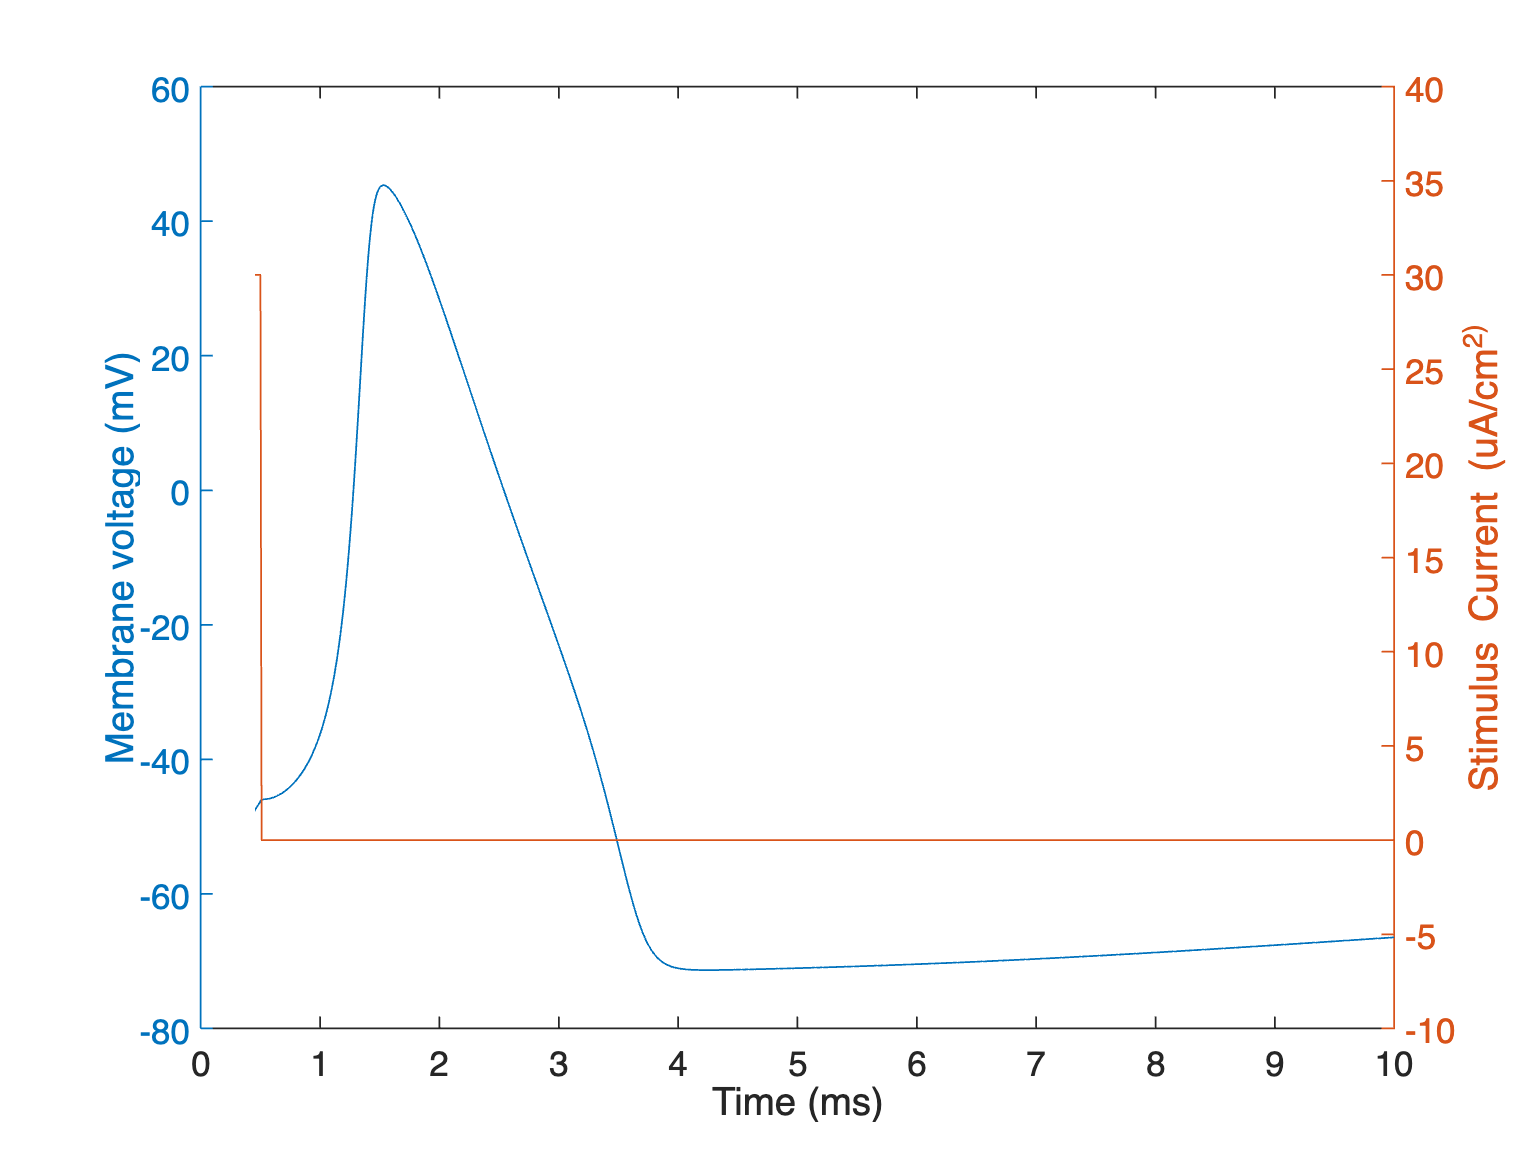

% Plot simulated membrane voltage (Vm) as a result of the applied stimulus current (Istim)
figure(1); clf;
yyaxis left;
plot(t, Vm);
xlabel('Time (ms)');
ylabel('Membrane voltage (mV)');
yyaxis right;
plot(t, stim);
xlabel('Time (ms)');
ylabel('Stimulus Current (uA/cm^2)');
ylim([-10 40]);

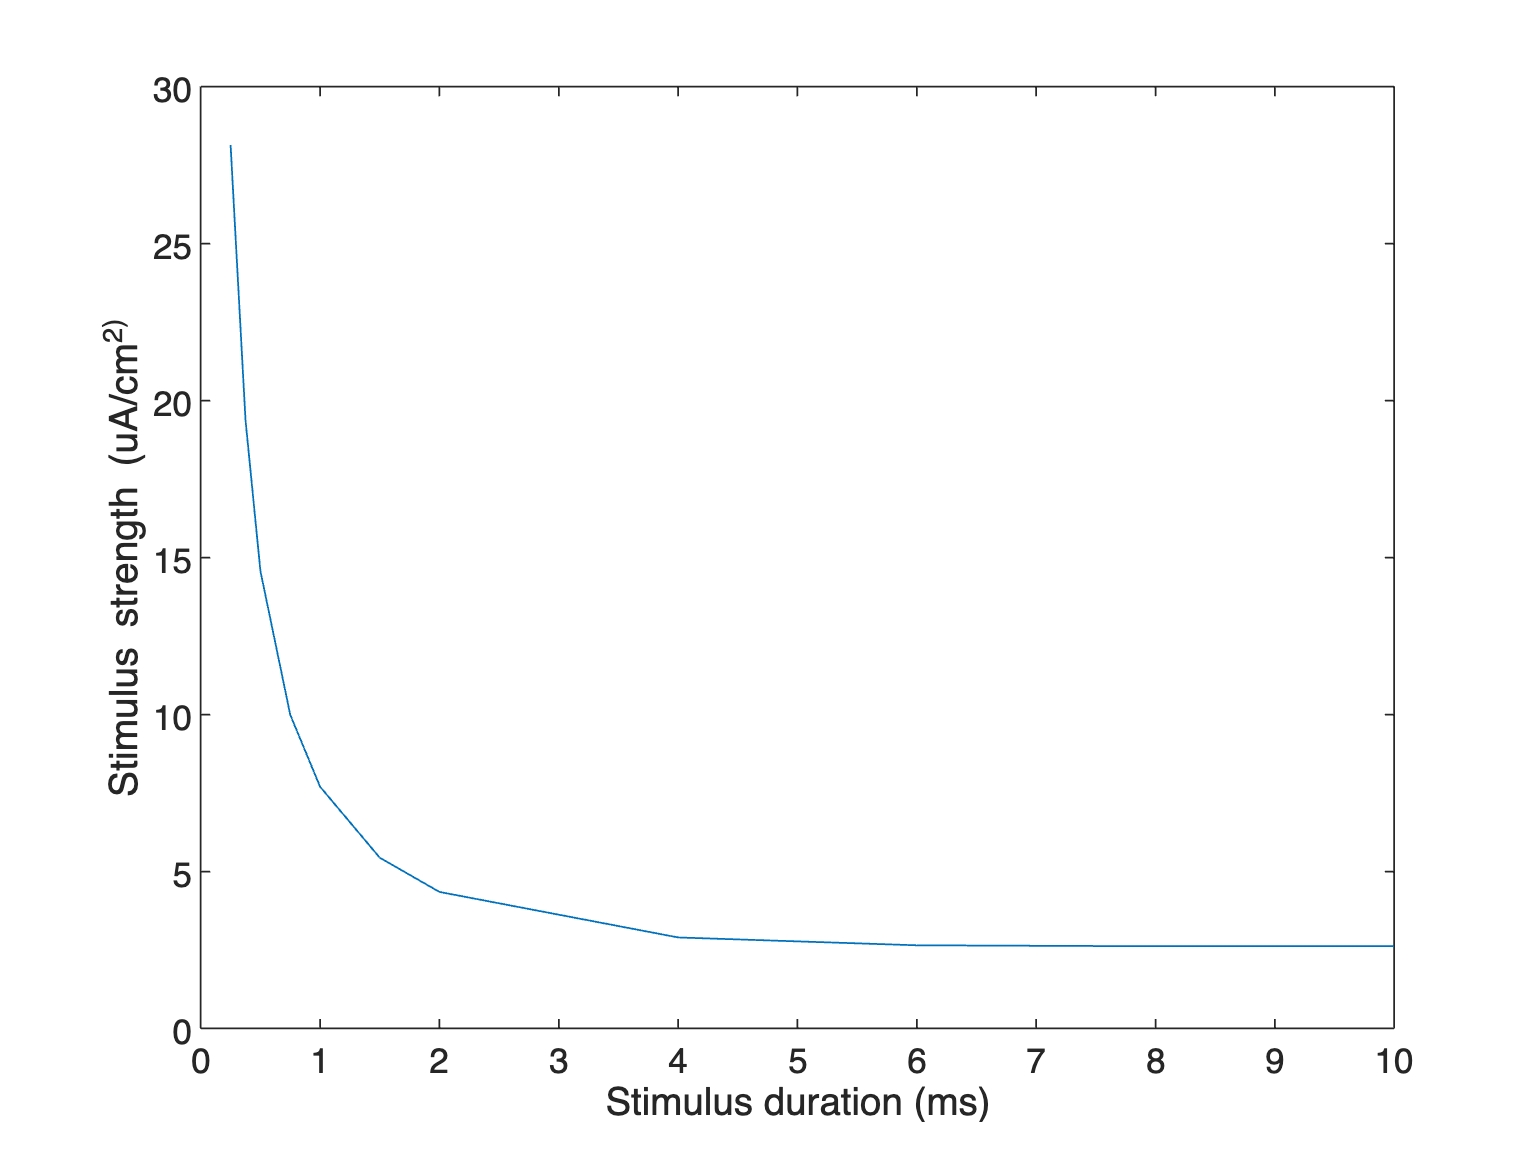


% Plot simulated potassium current (I_K) and sodium current (I_Na)
figure(2); clf;
plot(t, I_K, t, I_Na);
xlabel('Time (ms)');
ylabel('Ion Currents (uA/cm^2)');
legend('I_K', 'I_{Na}');

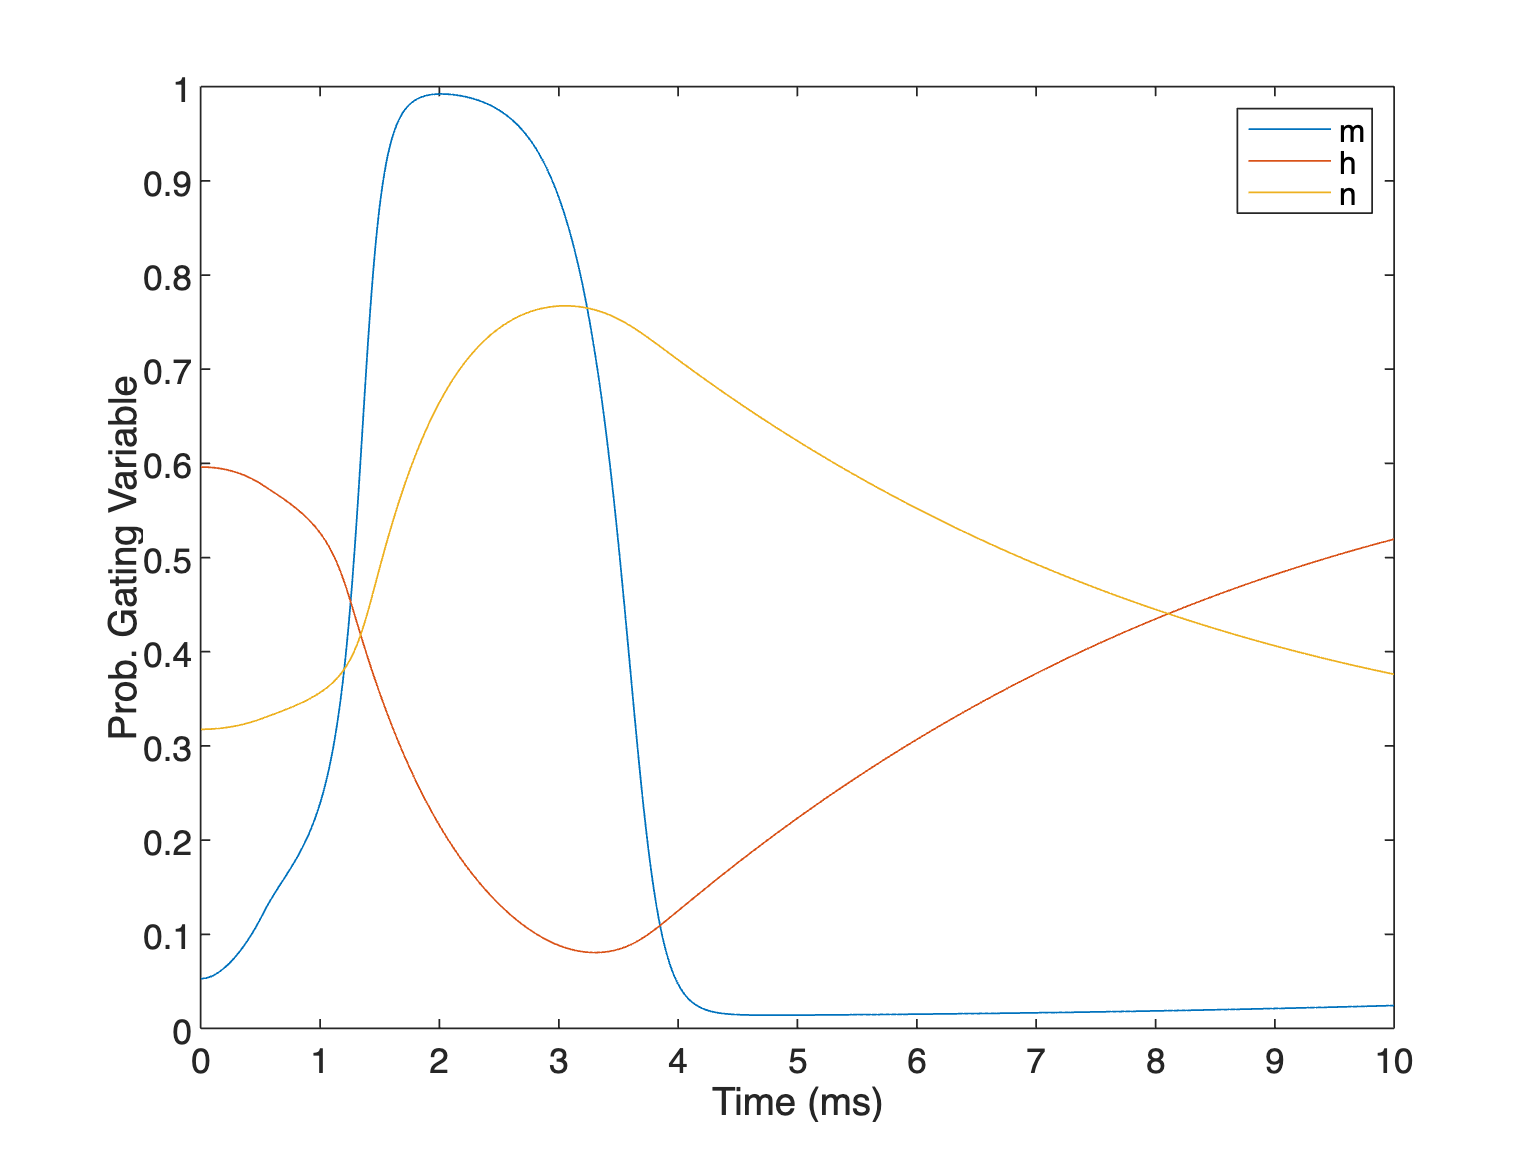


% Plot m, h and n
figure(3); clf;
plot(t, m, t, h, t, n);
xlabel('Time (ms)');
ylabel('Prob. Gating Variable');
legend('m', 'h', 'n');

## Verification exercises

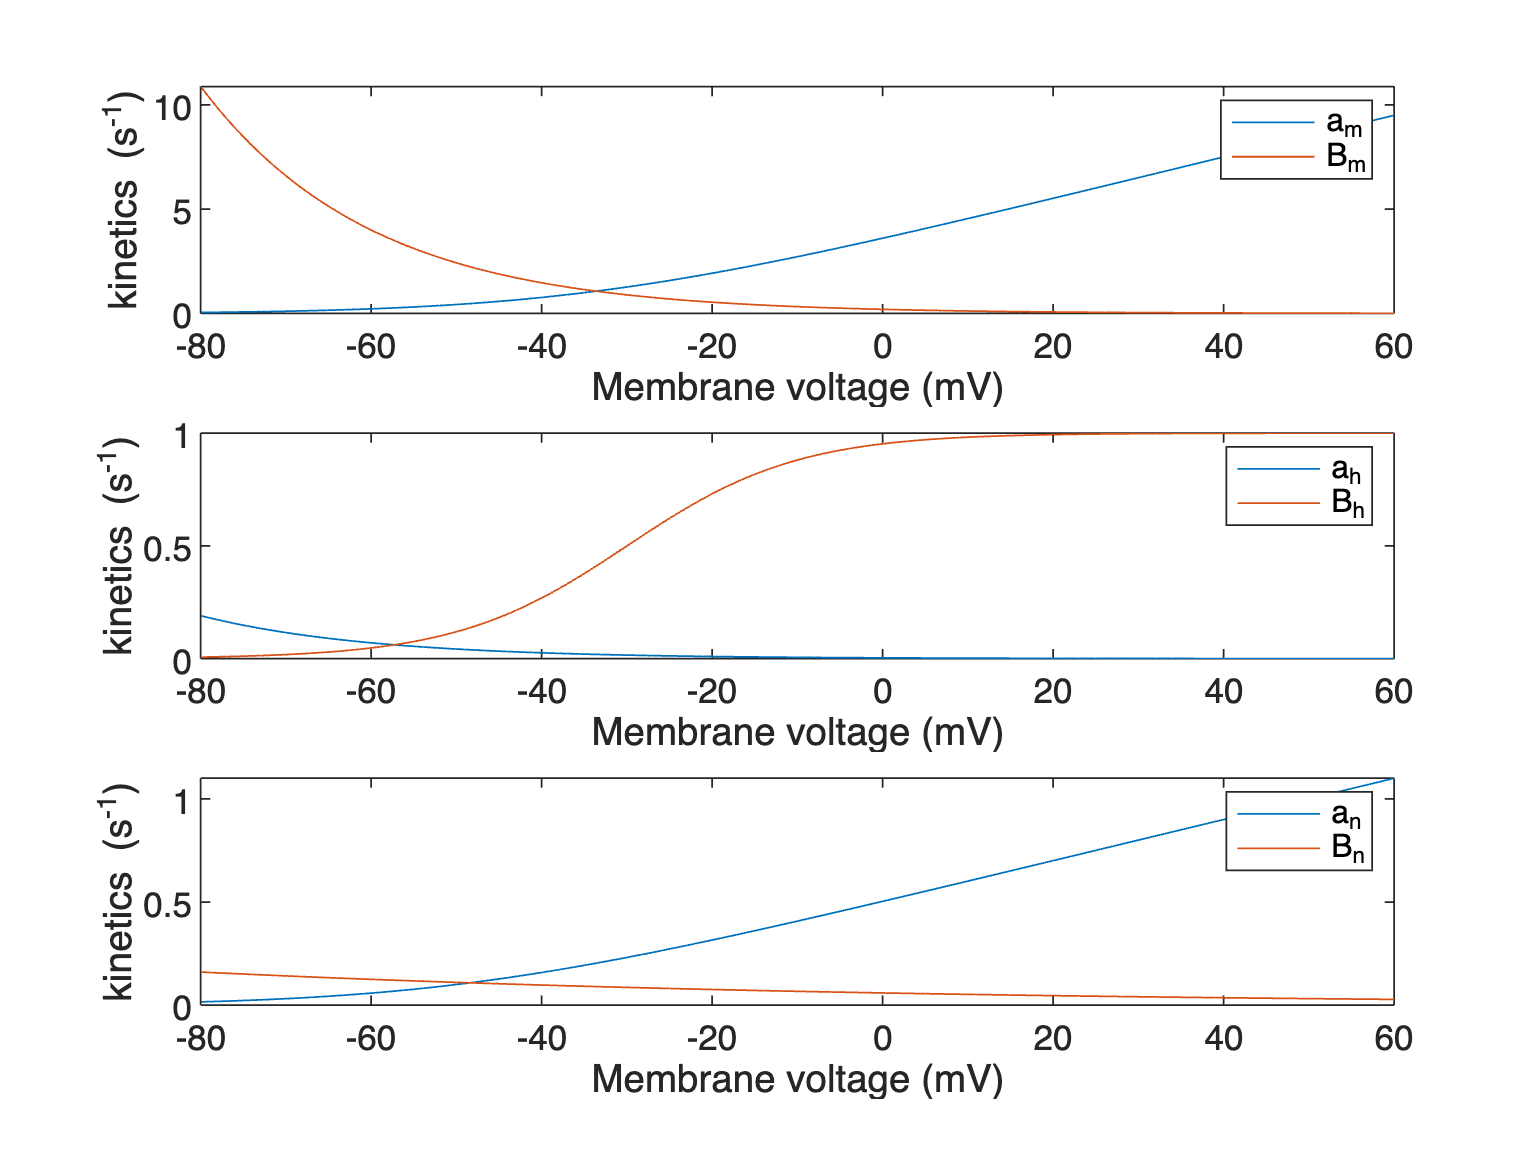

Vm_test = -80.00001:1:60.001;

alpha_m = zeros(1,length(Vm_test));
beta_m = zeros(1,length(Vm_test));
alpha_h = zeros(1,length(Vm_test));
beta_h = zeros(1,length(Vm_test));
alpha_n = zeros(1,length(Vm_test));
beta_n = zeros(1,length(Vm_test));

for V = 1:numel(Vm_test)
    alpha_m(V) = am(Vm_test(V));
    beta_m(V) = Bm(Vm_test(V));
    alpha_h(V) = ah(Vm_test(V));
    beta_h(V) = Bh(Vm_test(V));
    alpha_n(V) = an(Vm_test(V));
    beta_n(V) = Bn(Vm_test(V));
end

figure(6); clf
subplot(3,1,1);
plot(Vm_test, alpha_m, Vm_test, beta_m);
ylabel('kinetics (s^{-1})');
xlabel('Membrane voltage (mV)');
legend('a_m', 'B_m');
xlim([-80 60]);
hold on;
subplot(3,1,2);
plot(Vm_test, alpha_h, Vm_test, beta_h);
ylabel('kinetics (s^{-1})');
xlabel('Membrane voltage (mV)');
legend('a_h', 'B_h');
xlim([-80 60]);
subplot(3,1,3);
plot(Vm_test, alpha_n, Vm_test, beta_n);
ylabel('kinetics (s^{-1})');
xlabel('Membrane voltage (mV)');
legend('a_n', 'B_n');
xlim([-80 60]);